# Test of Cross Correlation Capabilities

### A. Locate image files

foldername = "21_20_02";
valid_files = dir(foldername + "/*." + "tif");
tracking_method = 'peaks';

num_images = length(valid_files);

The final line counts the number of images to be imported.

### B. Construct array of resized image data

images = [];
scale_fact = 1;

for i = 1:num_images
     images(:,:,:,i) = imresize(imread(foldername+"/"+valid_files(i).name),scale_fact,'bicubic');
end

A reference image is used for the `crosscorr` method and also to determine the number of channels

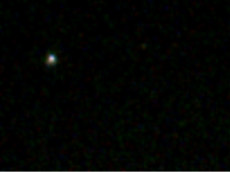

ans =   Image with properties:

                Data: [960×1280×3 uint8]
       Interpolation: "auto"
        DisplayRange: [0 255]
    DisplayRangeMode: "type-range"

           AlphaData: 1
              Parent: [1×1 Viewer]
             Visible: on


reference = images(:,:,:,1);
imageshow(uint8(reference))

num_channels = size(reference, 3);

### C. Apply relevant tracking method

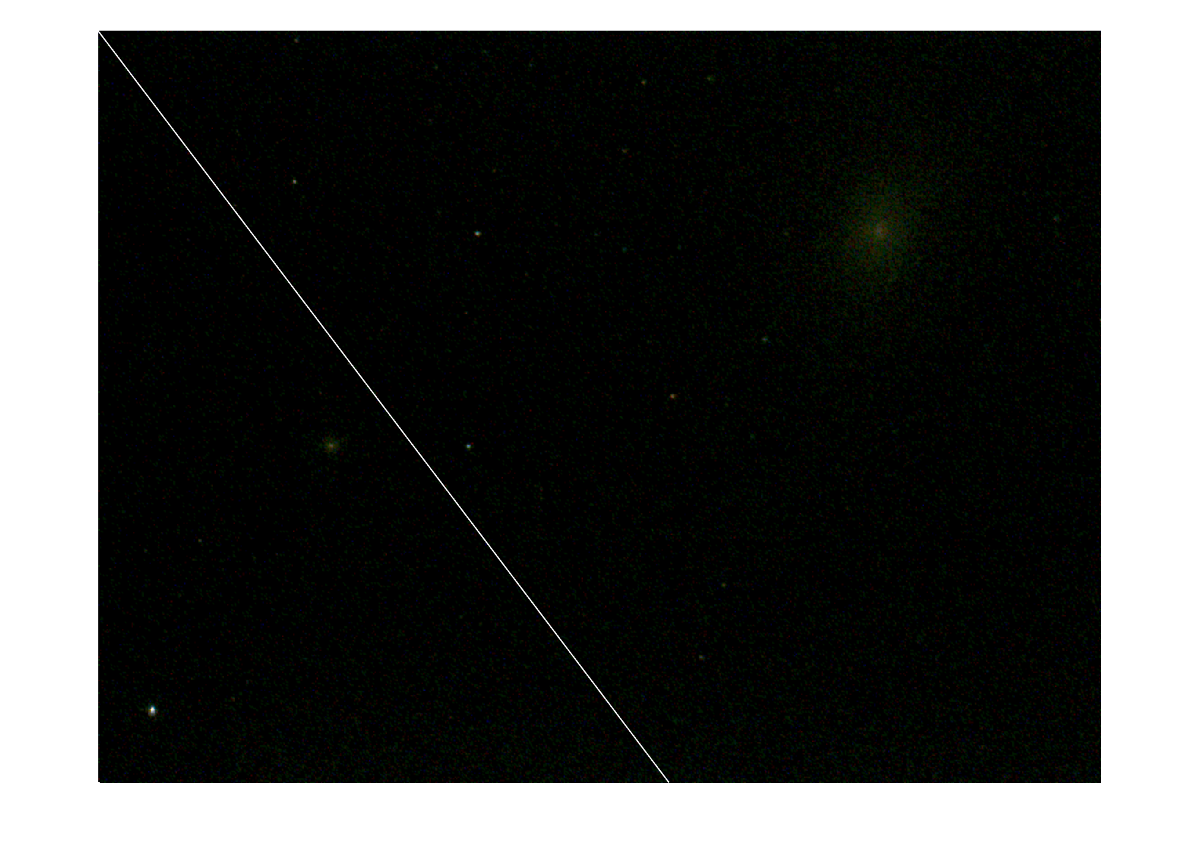

peaks = [];
centres = [] ;

gif 'crosscorr.gif'

for i = [10,20]
    current_image = images(:,:,:,i);
    current_image_channel = sum(current_image(:,:,:),3);
    [im_height, im_length] = size(current_image_channel);
    imshow(uint8(current_image))
    hold on
    xlim([0,im_length])
    ylim([0,im_height])
    

    reference_channel = sum(reference(:,:,:),3);
    
    mcorr = max(xcorr2(current_image_channel, reference_channel), [], 'all');
    [mcorrow, mcorrcol] = find(xcorr2(current_image_channel, reference_channel)  == mcorr);
    mcorrrow = round(mean(mcorrow));
    mcorrcol = round(mean(mcorrcol));

    for k = 1:20
        gif
    end

    plot([0,mcorrrow], [0,mcorrcol],'w-')

    % plotting these zeroes might not be accurate, need to talk with jamie
    % regarding method
    
    for k = 1:20
        gif
    end

    reference = current_image; % sets the next image reference to the last step
end